clc; clear all;
robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

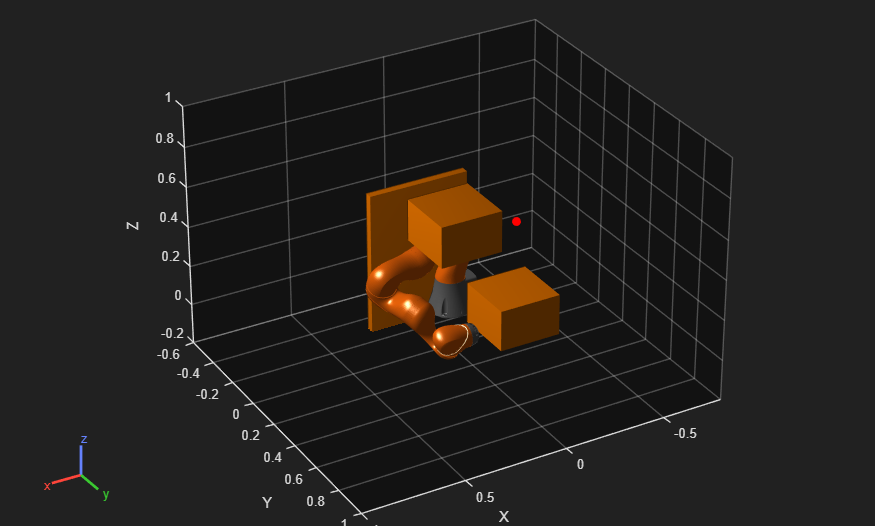

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';
helperCreateObstaclesKINOVA;

%%%%%%%%%%%%%%%% Scene 1 %%%%%%%%%%%%%%%%
% taskInit = trvec2tform([[0.3 0.0 0.4]])*axang2tform([0 1 1 pi]);
% taskFinal = trvec2tform([0.35 0.55 0.35])*axang2tform([0 1 0 pi]);  
% anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
% poseFinal = [taskFinal(1:3,4);anglesFinal'];
% ik = inverseKinematics('RigidBodyTree', robot);
% ik.SolverParameters.AllowRandomRestart = false;
% weights = [1 1 1 1 1 1];
%%%%%%%%%%%%%%%% Scene 1 %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%% Scene 2 %%%%%%%%%%%%%%%%
% taskInit = trvec2tform([[0.2 0.4 0.4]])*axang2tform([0 0 1 pi]);
% taskFinal = trvec2tform([-0.2 0.4 0.4])*axang2tform([0 0 1 pi]);  
% anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
% poseFinal = [taskFinal(1:3,4);anglesFinal'];
% ik = inverseKinematics('RigidBodyTree', robot);
% ik.SolverParameters.AllowRandomRestart = false;
% weights = [1 1 1 1 1 1];
%%%%%%%%%%%%%%%% Scene 2 %%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%% Scene 3 %%%%%%%%%%%%%%%%
taskInit = trvec2tform([[0.1 0.4 0.1]])*axang2tform([1 0 -1 pi]);
taskFinal = trvec2tform([-0.1 0.4 0.6])*axang2tform([1 0 1 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];
%%%%%%%%%%%%%%%% Scene 3 %%%%%%%%%%%%%%%%
currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);
finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,   world,"IgnoreSelfCollision","on"))

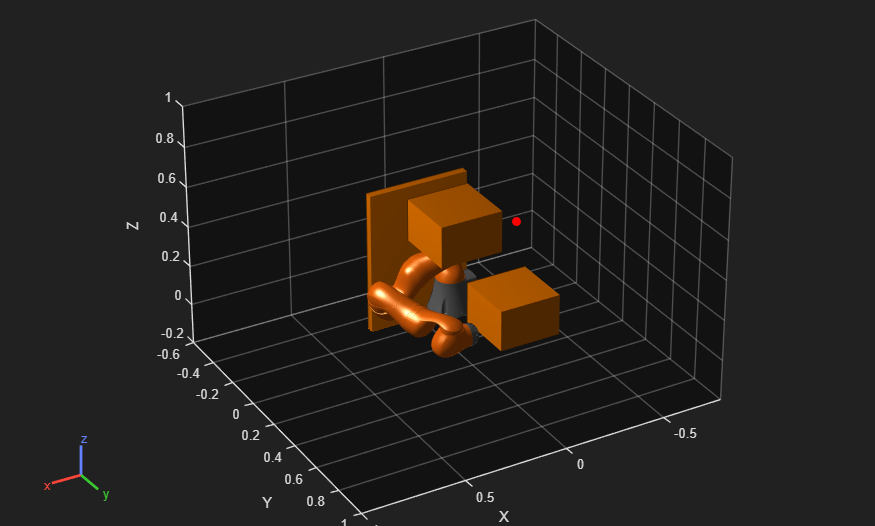

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 3.225097 seconds.


Qtheta = 129.5379

RAR = 45.4142

Elapsed time is 3.392263 seconds.


Qtheta = 114.5676

RAR = 45.4062

Elapsed time is 3.305563 seconds.


Qtheta = 101.0034

RAR = 45.4025

Elapsed time is 3.359029 seconds.


Qtheta = 92.8543

RAR = 45.3861

Elapsed time is 3.453729 seconds.


Qtheta = 77.2107

RAR = 45.3745

Elapsed time is 3.390618 seconds.


Qtheta = 70.3538

RAR = 45.3794

Elapsed time is 3.432320 seconds.


Qtheta = 67.6474

RAR = 45.3872

Elapsed time is 3.406755 seconds.


Qtheta = 63.4428

RAR = 45.3825

Elapsed time is 3.388483 seconds.


Qtheta = 57.4862

RAR = 45.3660

Elapsed time is 3.381343 seconds.


Qtheta = 52.2785

RAR = 45.3584

Elapsed time is 3.327103 seconds.


Qtheta = 55.1624

RAR = 45.3616

Elapsed time is 3.411561 seconds.


Qtheta = 51.8321

RAR = 45.3493

Elapsed time is 3.334701 seconds.


Qtheta = 47.1679

RAR = 45.3529

Elapsed time is 3.358813 seconds.


Qtheta = 46.7079

RAR = 45.3539

Elapsed time is 3.310162 seconds.


Qtheta = 47.9204

RAR = 45.3587

Elapsed time is 3.240480 seconds.


Qtheta = 48.0413

RAR = 45.3588

Elapsed time is 3.289732 seconds.


Qtheta = 46.9798

RAR = 45.3663

Elapsed time is 3.309521 seconds.


Qtheta = 46.4828

RAR = 45.3598

Elapsed time is 3.300552 seconds.


Qtheta = 46.4738

RAR = 45.3529

STOMP Finished.


isTrajectoryInCollision = logical
   1


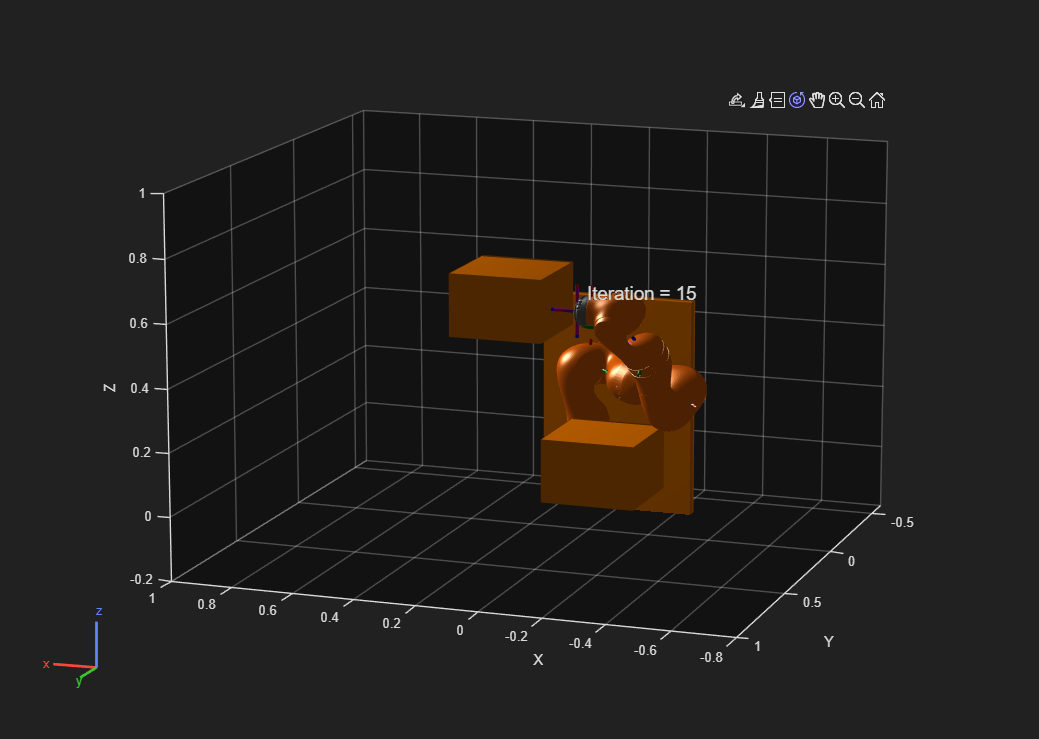

enableVideoTraining = 1;
enableVideo = 1;
helperSTOMP;